# Oxcart data reconstruction

## loading and cropping of data

raw = oxcartRawDataImport();
numHits = height(raw); % number of detector hits in file
hitIdx = (1:numHits)'; % index of hit variable


### conversion to real word units

tofBinSize = 13.717; % ps, value for unbinned
t0 = 25; % ns, time offset of tdc in detection system
xBin = 0.01637; % mm/bin, conversion of detector bins to real world units
detCenter = [4500, 4000]; % center of detector in detector bins

det = oxcartConvertRawData(raw, tofBinSize , t0, xBin, detCenter);

clear tofBinSize t0 xBin detCenter

### cropping in tof history

plotting tof history

numHits = height(det)

numHits = 3378662

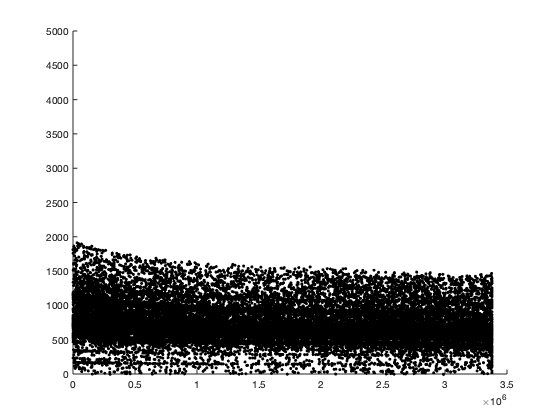

sampleSize = .8e6; % number of points used for tof visualisation
sample = randsample(numHits,sampleSize);

tofAx = axes(figure('Name','tof evolution'));
scatter(hitIdx(sample),det.tof(sample),'.k');
tofAx.YLim = [0 5000];

getting limits

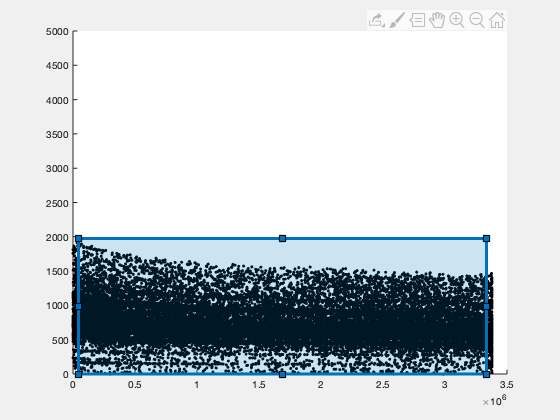

tofRoi = drawrectangle(tofAx);

inTof = hitIdx > tofRoi.Vertices(1,1) & hitIdx < tofRoi.Vertices(3,1);
tofCropLossPct = (1 - nnz(inTof)/height(det))*100

tofCropLossPct = 1.3480


det = det(inTof,:);

### cropping in detector space

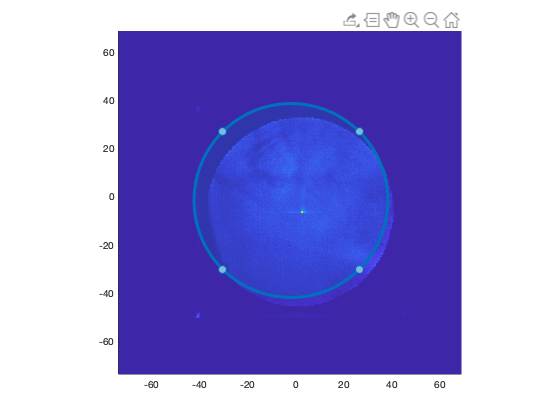

FDMresolution = 512; % pixels for FDM
FDMax = axes(figure());

FDM = fieldDesorptionMap(det.detx,det.dety,FDMresolution, FDMax); 
axis equal;
axis tight
detRoi = drawcircle(FDMax);

% select detector region of interest

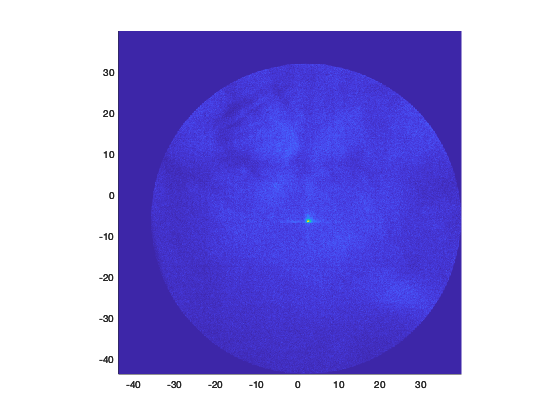

detectorDist = sqrt((det.detx - detRoi.Center(2)).^2 + (det.dety - detRoi.Center(1)).^2);
in = detectorDist < detRoi.Radius;
numHits = height(det);

det2 = det(in,:);

FDM = fieldDesorptionMap(det2.detx,det2.dety,FDMresolution, axes()); 
axis equal
axis tight


tofCropLossPct = (1 - height(det2)/height(det))*100

tofCropLossPct = 5.9895

det = det2;
clear det2